# IAVSD23 - Optimizing rail maintenance

## Input data (lookup table for H-index)

clearvars % clear all variables in the workspace

%%% Lookup tables (sheet names in the excel input file)
tonnage = "H_30t";% standard axle load (30 tons), alternatively "H_32t" for heavy axle load (32.5 tons)

%%% Given the axle load, read H-indices in the lookup tables for both MB5 and MB6
[H_table_MB5,~,risk_MB5,~] = read_input_data(tonnage);

%%% plot table
% plot_figure('H_table5_heatmap', H_table_MB5);

## Interpolation and preprocessing for MB5

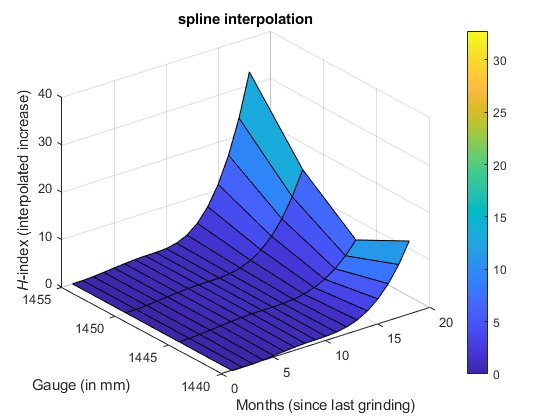

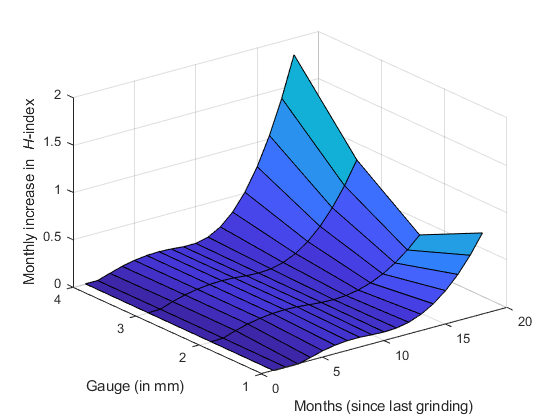

%%% set interpolation method
interpolation_method = 'spline';% alternatively, 'linear', 'makima', 'cubic', or 'spline'

%%% set the maximal frequency for grinding activity
grinding_freq_max = 18; % in months, i.e., max number of months beforing grinding

%%% interpolations of H_table for MB5
H_interpolated_MB5 = interpolation(H_table_MB5,interpolation_method, grinding_freq_max, tonnage);

%%% visualize the interpolated H_tables (and the average monthly deterioration in H-index)
plot_figure(strcat(interpolation_method,' interpolation'), H_interpolated_MB5)


%%% get maximal lifetimes
[max_lifetime_MB5] = get_max_lifetime(risk_MB5);

## LCC Simulation for different maintenance strategies

%%% set the simulation paramters
avg_yearly_gauge_widening = 5; % average yearly gauge widening (in mm/year)
tamping_freq_max = 48; % max number of months before tamping

%%% initializations
months_tamping = 1:tamping_freq_max;
months_grinding = 1:grinding_freq_max;
simulation_LCC_MB5 = zeros(months_grinding(end),months_tamping(end));
rail_lifetime_MB5 = zeros(months_grinding(end),months_tamping(end));

%%% find the optimal (LCC-minimal) strategies for tamping and grinding
for grinding_freq=months_grinding % different grinding frequencies
    for tamping_freq=months_tamping % different tamping frequencies
        %%% set strategy
        maint_strategy = [grinding_freq,tamping_freq];
        %%% calculate LCC (annuity)
        [simulation_LCC_MB5(grinding_freq,tamping_freq),rail_lifetime_MB5(grinding_freq,tamping_freq)] = ...
            get_lcc(H_interpolated_MB5, maint_strategy, interpolation_method, "MB5", avg_yearly_gauge_widening, max_lifetime_MB5);
    end
end

## Plot simulation results

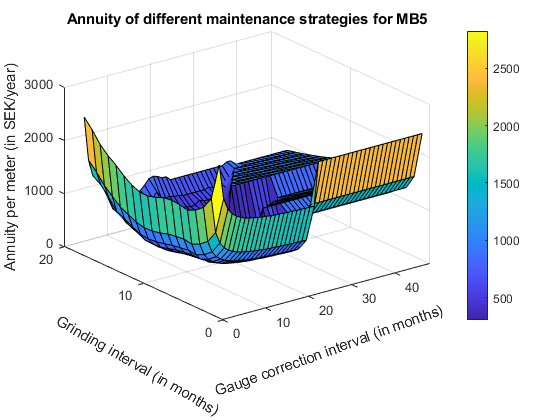

%%% plot the variation of LCC/annuity for different maintenance strategies
plot_figure('LCC_heatmap MB5', simulation_LCC_MB5);


%%% get optimal/minimal annuity
min_annuity_MB5 = min(simulation_LCC_MB5(:))

min_annuity_MB5 = 304.6129


%%% get the corresponding optimal strategy (or strategies)
[row_grinding,col_tamping] = find(simulation_LCC_MB5==min_annuity_MB5)

row_grinding = 11

col_tamping = 24


%%% get the corresponding optimal rail lifetime
lifetime_MB5 = rail_lifetime_MB5(row_grinding(1), col_tamping(1))

lifetime_MB5 = 12